clear; clc; close all;

u= @(t) heaviside(t)

u = function_handle with value:
    @(t)heaviside(t)


x= @(t) t

x = function_handle with value:
    @(t)t


f= @(t) x(t).*(2.*u(t)-u(t+4)-u(t-2))

f = function_handle with value:
    @(t)x(t).*(2.*u(t)-u(t+4)-u(t-2))


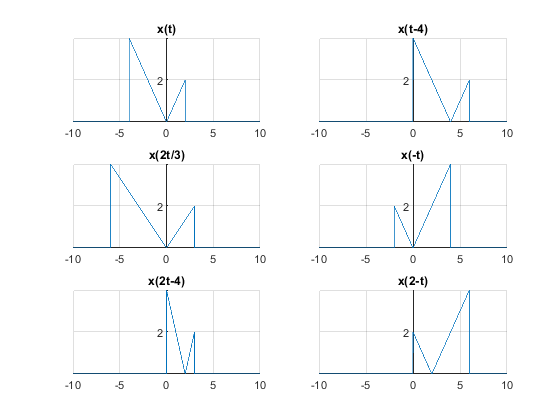


t=-10:0.001:10;

for i=1:6
    subplot(3,2,i)
    switch i
        case 1
            F=f(t); plot(t,F); title('x(t)')
        case 2
            F=f(t-4); plot(t,F); title('x(t-4)')
        case 3
            F=f(2*t/3); plot(t,F); title('x(2t/3)')
        case 4
            F=f(-t); plot(t,F); title('x(-t)')
        case 5
            F=f(2*t -4); plot(t,F); title('x(2t-4)')
        case 6
            F=f(2-t); plot(t,F); title('x(2-t)')
    end
    grid on; ax = gca; ax.Box = 'off';
    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
end